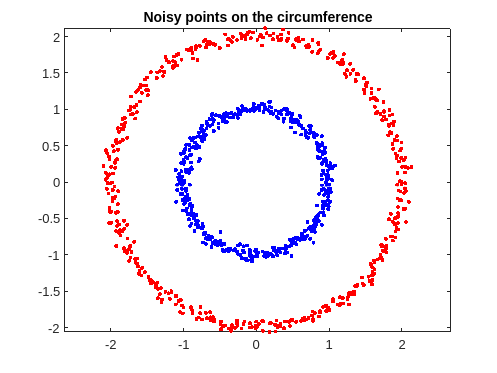

% Number of points
N = 1000;

% Generate angles uniformly from 0 to 2*pi
theta = linspace(0, 2*pi, N/2);

% Compute x and y coordinates without noise
x1 = [cos(theta);sin(theta)];

% Add small noise to x
noise_level = 0.05; % Adjust this value as needed
x1_noisy = x1 + noise_level * randn(2, N/2);

% Compute x and y coordinates without noise
x2 = [2*cos(theta);2*sin(theta)];

% Add small noise to x
noise_level = 0.05; % Adjust this value as needed
x2_noisy = x2 + noise_level * randn(2, N/2);

% Plot the noisy points
figure;
plot(x1_noisy(1,:),x1_noisy(2,:), 'b.');
hold on
plot(x2_noisy(1,:),x2_noisy(2,:), 'r.');
hold off
axis equal;
title('Noisy points on the circumference');

tr1_in = mat2cell(x1_noisy(:), 2*ones(1, N/2));
tr2_in = mat2cell(x2_noisy(:), 2*ones(1, N/2));

tr_in = cat(1, tr1_in, tr2_in);
tr_tg = categorical([zeros(N/2,1);ones(N/2,1)]);

omega_b = 0;
Nh = 2;
ts = 1000;
%f = @(bias, hidden_weights, hidden) tanh(hidden_weights*hidden + bias);
f = @(bias, hidden_weights, hidden) hidden_weights*hidden + bias;
phi = @eulerForward;
eps = 0.001;
eigs = {[3 3], [1]};
ws = 0;
lambda_r = 0.1;
%Nl = 1;
seed = 1;

addpath src

net = NeuralODE(omega_b, Nh, ts, f, phi, eps, eigs, ws, lambda_r, seed);

hidden = net.hiddenState(tr_in);

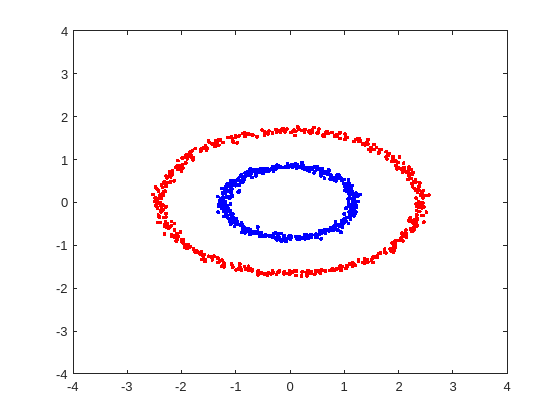

% Animation loop
hidden_mat = cell2mat(hidden);

num_iterations = ts+1;
for iteration = 1:num_iterations
    % Update positions
    hidden_iteration = hidden_mat(:,iteration);
    hidden_iteration = reshape(hidden_iteration, [2, N]);
    x1 = hidden_iteration(1,1:N/2);
    y1 = hidden_iteration(2,1:N/2);
    x2 = hidden_iteration(1,N/2+1:N);
    y2 = hidden_iteration(2,N/2+1:N);
    
    % Clear the previous positions of the points
    clf;
    % Plot the points
    plot(x1, y1, 'b.');
    hold on
    plot(x2, y2, 'r.');
    hold off
    axis([-4 4 -4 4]); % Assuming points are within [-4,4]x[-4,4]
    drawnow; % Refresh the plot
    
    % Pause for a short duration
    pause(0.05);
end

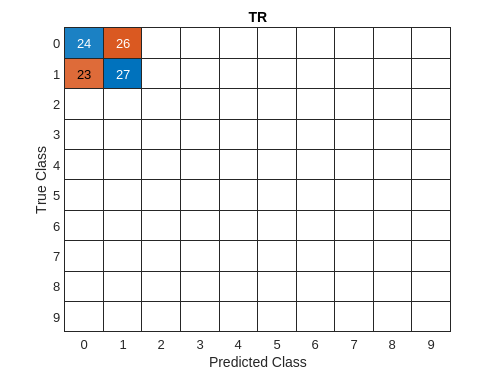

[net,pred_tr]=net.fit(tr_in,tr_tg);
figure
confusionchart(tr_tg, pred_tr);
title("TR")